out.RMSE_power.signals.values(isinf(out.error_power.signals.values)|isnan(out.error_power.signals.values)) = 0;
out.RMSE_voltage.signals.values(isinf(out.error_power.signals.values)|isnan(out.error_power.signals.values)) = 0;
out.error_power.signals.values(isinf(out.error_power.signals.values)|isnan(out.error_power.signals.values)) = 0;
out.error_voltage.signals.values(isinf(out.error_power.signals.values)|isnan(out.error_power.signals.values)) = 0;

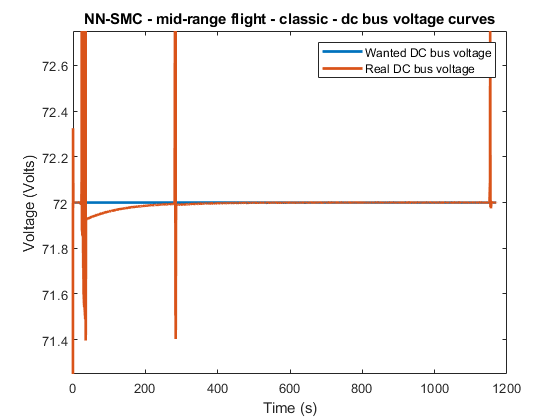

type_EMS = 'NN-SMC';
if t(end)<1000
    type_flight = ' - low';
else
    type_flight = ' - mid';
end
sav = 'save';
wth = 2;

name_file = strcat(type_EMS,' ',type_flight,'-range flight');
dir_ = strcat('D:\CHINE\EMS-2\',type_EMS);

bus_curve_final(out,strcat(name_file,' - classic'),dir_,sav,wth);

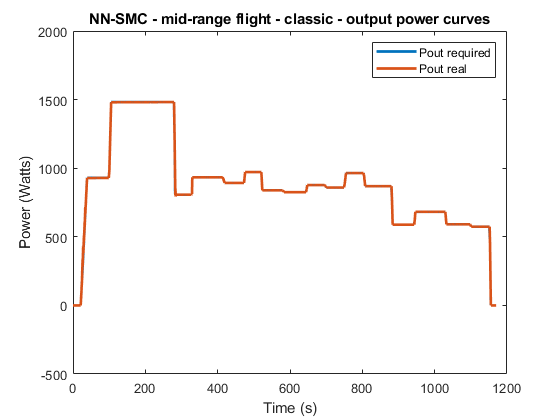

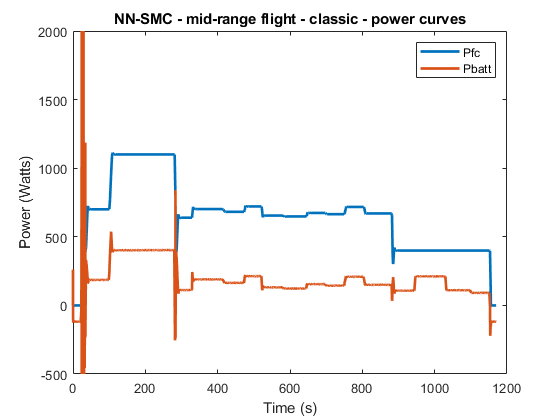

power_curve_final(out,strcat(name_file,' - classic'),dir_,sav,wth);

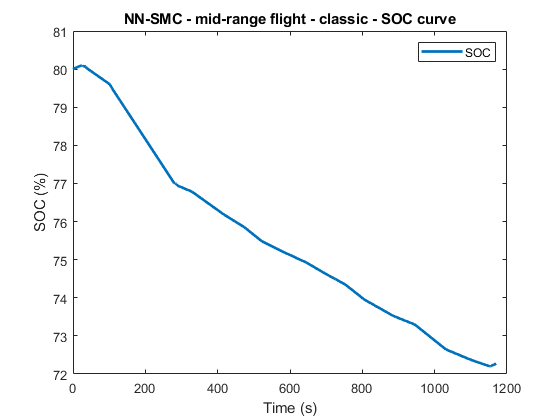

soc_curve_final(out,strcat(name_file,' - classic'),dir_,sav,wth);


gcf = global_cost_funciton(out.Pfc_in.signals.values,out.Ifc.signals.values,...
    out.Ibatt.signals.values',out.SOC_batt.signals.values',out.tout)

gcf = 235.9664


table_data(out,gcf,name_file,dir_,sav)

ans = 14×1 table
                              col  
                            _______

    gcf                      235.97
    Pfc_in                   650.26
    Pbatt_in                 184.12
    Ppv_in                   144.56
    Vdc_real                     72
    SOC_batt                  72.27
    RMSE_power                  1.7
    RMSE_voltage               0.17
    error_power                0.05
    error_voltage              0.02
    dVdc                    0.53942
    exec time                148.53
    Percentage time          12.694
    hydrogen consumption     11.584


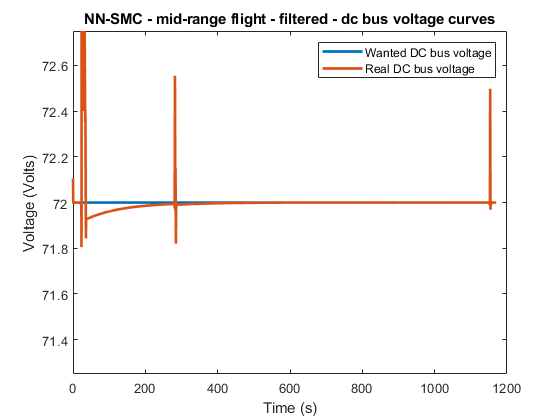




out_2 = filter_sgo(out);

bus_curve_final(out_2,strcat(name_file,' - filtered'),dir_,sav,wth);

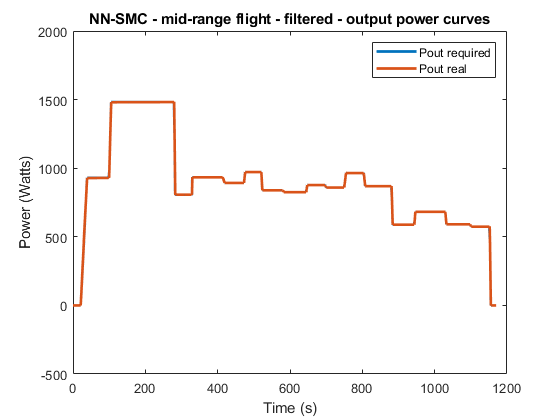

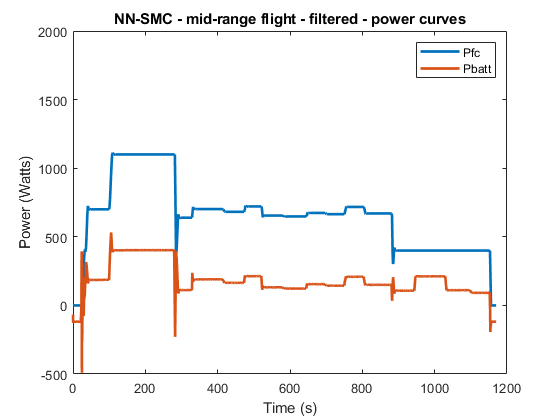

power_curve_final(out_2,strcat(name_file,' - filtered'),dir_,sav,wth);

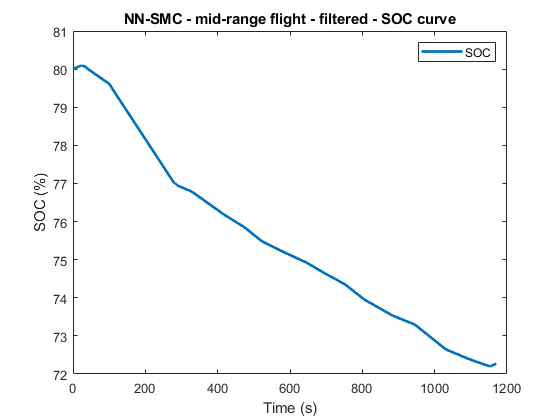

soc_curve_final(out_2,strcat(name_file,' - filtered'),dir_,sav,wth);


% gcf_2 = global_cost_funciton(out_2.Pfc_in.signals.values,out_2.Ifc.signals.values,...
%     out_2.Ibatt.signals.values',out_2.SOC_batt.signals.values',out_2.tout)
%
% table_data(out_2,gcf_2,'')

clear out_2
